## **Tube Classifier | Train & Test**

This Live Script allows new model training, batch testing, as well as single image tests. To get started, press 'run' in the section that corresponds to your intended output. The following sections can be run: 

- Train: trains a new model using the full MPDD set of images. Saves a new model along with a folder called 'testImages' containing the images used for validation and to be used for future batch testing.

- Batch Test: Performs a Batch test on the 'testImages' file. The function generates two confusion matrices, the first shows all classifications with a row summary displaying the percentage of correct/incorrect classifications. An additional confusion matrix only compares the pass/fail classifications. Finally, yield rates and defect rates are calculated and displayed. The escaped defect rate shows how many 'failed' parts were classified as a 'pass' by the AI classifier. Ideally, this value is 0.00%.

- Single Image Test: Classifies a single image and generates a detailed output report. Optionally, a comparison of the test set mask and generated mask can be displayed.

*Note: if you downloaded the test images set and provided model from the GitHub, you do not need to train a new model, otherwise, download the full MPDD set and begin with this function.*

Testing can be further personalized using the drop-downs/sliders listed in each section (if any).

### Train Model

Detected 4 classes to learn.
    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:08       0.0001                            2.1646                                    11.111
            1        1       00:00:09       0.0001          2.0856                                  6.25                      
           10        1       00:00:42       0.0001         0.83838           0.86523                  75                71.111
           20        2       00:01:14       0.0001         0.27178           0.46213                 100                84.444
           30        3       00:01:46       0.0001         0.18053           0.23386               93.75                91.111
           40        4       00:02:18       0.0001         0.09009           0.136

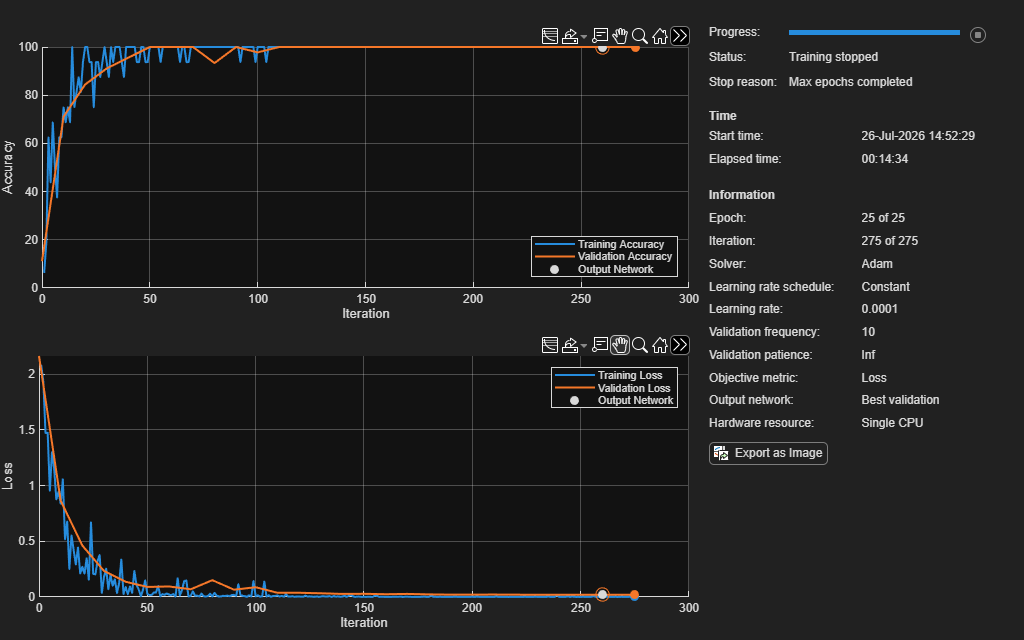

% ---> Run Training Section

 

% ---> USER SETTINGS 

chosenDataset = "tubes"; % Only 1 Dataset as of 7/26/26

% ---> CODE STARTS HERE
% ---> DO NOT MODIFY BELOW THIS POINT)

% Obtain the file location of the dataset. 
fileLoc = sprintf("MPDD/%s/test", chosenDataset);

% Creates an image Datastore to store all images of specified subset type.
% The image Datastore is setup to specifically look for images with certain file
% extensions that are common for images (i.e. jpg, png, etc.)
ds = imageDatastore(fileLoc, 'IncludeSubfolders',true, 'LabelSource','foldernames', ...
    'FileExtensions', ["*.jpg", "*.png", "*.tiff"]);

% Creates an AI Model in local directory called "tubeClassifierNet.mat"
% saves a test set used for validation as a folder 'testImages'
training(ds);

### Batch Testing

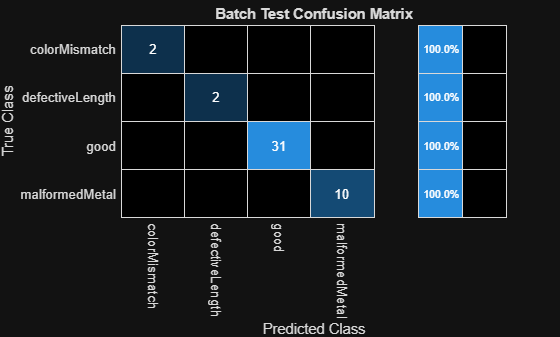

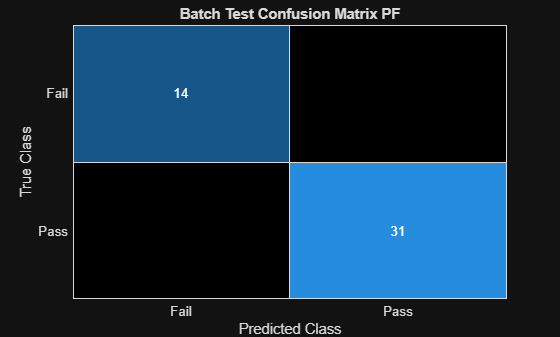

Actual Yield: 68.9%
Predicted Yield 68.9%

Defect Rate: 31.1%
Escaped Defect Rate 0.0%



% ---> Run Batch Testing Section

 

% ---> USER SETTINGS 

Image_Condition = "Normal"; % Image condition
% Recommended Brightness Factor: 0.75
% Recommended Blur Factor: 0.1
% Recommended Noise Factor: 0.25
Brightness_Factor = 0.75; % Higher values apply a larger brightness amplification
Blur_Factor = 0.1; % Higher values apply a larger Blur amplification
Noise_Factor = 0.25; % Higher values apply a larger Noise amplification
Noise_Type = "speckle"; % Recommended: 'Speckle'

% ---> CODE STARTS HERE
% ---> DO NOT MODIFY BELOW THIS POINT)

% Loads test image dataset
testDS = imageDatastore("testImages", 'IncludeSubfolders',true, 'LabelSource','foldernames', ...
    'FileExtensions', ["*.jpg", "*.png", "*.tiff"]);
numFiles = numel(testDS.Files);

% IMAGE FILTERING

% Apply brightness to each image if set to 'bright'
if Image_Condition == "Bright"
    ll = 0.4 * Brightness_Factor; % lower limit
    ul = 1 - (0.4 * Brightness_Factor); % upper limit
    testDS.ReadFcn = @(filename) imadjust(imread(filename), [ll ll ll; ul ul ul], []);
% Apply Blur to each image if set to 'blur'
elseif Image_Condition == "Blurry"
    Blur = 50 * Blur_Factor;
    testDS.ReadFcn = @(filename) imgaussfilt(imread(filename), Blur);
% Apply Noise to each image if set to 'Noisy'
elseif Image_Condition == "Noisy"
    testDS.ReadFcn = @(filename) imnoise(imread(filename), Noise_Type, Noise_Factor);
% Normal image otherwise
else
    testDS.ReadFcn = @(filename) imread(filename);
end

% Inspects the chosen batch using the trained AI model, outputs a confusion
% matrix
runBatchInspection(testDS);

### Single Image Inspection

% ---> Run Image Inspection Section

 

% ---> USER SETTINGS 

imageType = "malformedMetal"; % <-- Defect Type of Image
imgNum = 70; % <-- Number of image in subset
compareMasks = true; % <-- If enabled, a mask comparison will be displayed

% ---> CODE STARTS HERE
% ---> DO NOT MODIFY BELOW THIS POINT)

% Check that image number was valid
folder = sprintf("%s/MPDD/%s/test/%s", pwd, chosenDataset, imageType); % Finds Folder 
numFiles = numel(dir(folder)) - 2; % Count number of files in the folder 
if imgNum > numFiles 
   errMsg = sprintf("Warning: the selected category only has %d images. " + ...
       "The selected value '%d' has been set to 1 as a result.", numFiles, imgNum);
   disp(errMsg);
   imgNum = 1;
end

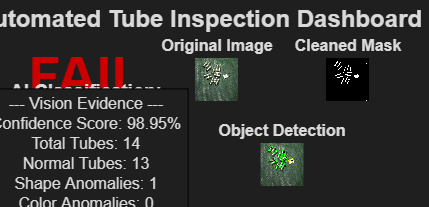


% Find and load chosen image
fileLoc = sprintf("%s/%s%03d.png", folder, imageType, imgNum);
img = imread(fileLoc);

% Generate Output
reportData = singleImageInspectionFunction(img, true);
displayInspectionOutput(img, reportData);

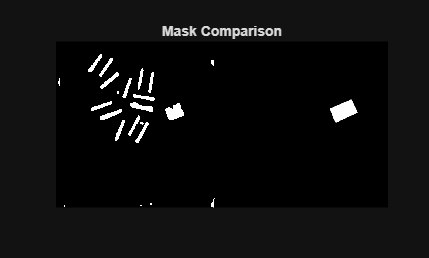


if compareMasks
    % Grab folder location for masks and loaf the mask image
    folder = sprintf("%s/MPDD/%s/%s_ground_truth/%sMask", ...
        pwd, chosenDataset, chosenDataset, imageType);
    fileLocMask = sprintf("%s/%s%03dMASK.png", folder, imageType, imgNum);
    imgMask = imread(fileLocMask);

    figure;
    montage({reportData.images.ImageMask, imgMask});
    title("Mask Comparison");
end

## Image Filter Testing

The following code can be run to see the output result of various image filtering. This can be used prior to batch testing to see the impact of changing various settings.

% ---> Run Filter Testing Section

 

% ---> USER SETTINGS 

% SELECT AN IMAGE
imageType = "malformedMetal"; % <-- Defect Type of Image
imgNum = 70; % <-- Number of image in subset

% SELECT FILTER
Image_Condition = "Noisy"; % Image condition
% Recommended Brightness Factor: 0.75
% Recommended Blur Factor: 0.1
% Recommended Noise Factor: 0.25
Brightness_Factor = 0.75; % Higher values apply a larger brightness amplification
Blur_Factor = 0.1; % Higher values apply a larger Blur amplification
Noise_Factor = 0.25; % Higher values apply a larger Noise amplification
Noise_Type = "speckle"; % Recommended: 'Speckle'

% ---> CODE STARTS HERE
% ---> DO NOT MODIFY BELOW THIS POINT)

% Check that image number was valid
folder = sprintf("%s/MPDD/%s/test/%s", pwd, chosenDataset, imageType); % Finds Folder 
numFiles = numel(dir(folder)) - 2; % Count number of files in the folder 
if imgNum > numFiles 
    errMsg = sprintf("Warning: the selected category only has %d images. " + ...
        "The selected value '%d' has been set to 1 as a result.", numFiles, imgNum);
    disp(errMsg);
    imgNum = 1;
end

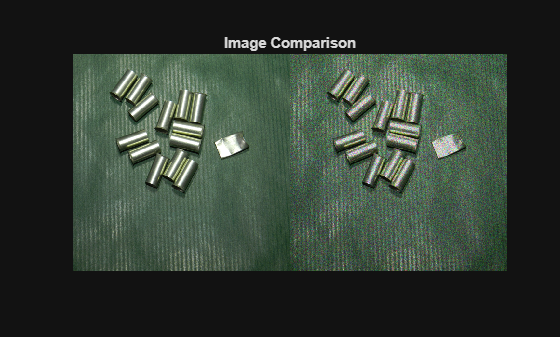


% Find and load chosen image
fileLoc = sprintf("%s/%s%03d.png", folder, imageType, imgNum);
img = imread(fileLoc);

% Image filtering
% Apply brightness to image if set to 'bright'
if Image_Condition == "Bright"
    ll = 0.4 * Brightness_Factor; % lower limit
    ul = 1 - (0.4 * Brightness_Factor); % upper limit
    imgAdj = imadjust(img, [ll ll ll; ul ul ul], []);
    % Apply Blur to image if set to 'blur'
elseif Image_Condition == "Blurry"
    Blur = 50 * Blur_Factor;
    imgAdj = imgaussfilt(img, Blur);
    % Apply Noise to image if set to 'Noisy'
elseif Image_Condition == "Noisy"
    imgAdj = imnoise(img, Noise_Type, Noise_Factor);
    % Normal image otherwise
end

% Display comparison
figure;
montage({img, imgAdj});
title("Image Comparison");